# Opgave 3: Stokastiske processer

En WSS (stationær) og ergodisk diskret-tids stokastisk proces Y[n] er defineret som: 

Y[n]= 3 ∙ X[n] + W[n] 

hvor X[n] ~U(1,3) er i.i.d. (uafhængigt og ens fordelt) og W[n] ~N(0,0.5) er i.i.d. Desuden er X[n] og W[n] indbyrdes uafhængige

**a) Plot tre realisationer af processen Y[n], hvor der medtages 10 samples af Y[n]. Brug en tilfældighedsgenerator og vis med kode (Matlab, Maple, Prime, Python el.lign.) hvordan realisationen er fremkommet. I Matlab kan rand() og randn() benyttes. **

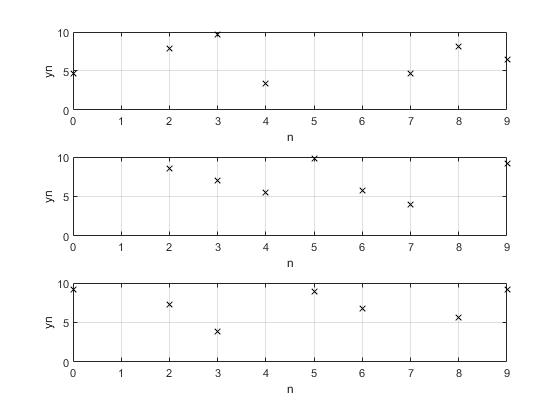

for i=1:3
wn_Sigma = sqrt(0.5);
wn_mu=0;
wn=(rand(1,10)*wn_Sigma)+wn_mu;

xn_Sigma = 3;
xn_mu=1;
xn=(rand(1,10)*xn_Sigma)+xn_mu;

yn=3*xn+wn;

figure(1)
ax=subplot(3,1,i);
n=0:9;
plot(ax,n,yn,'kx')
grid
axis([0,9,0,10])
xlabel(ax, 'n')
ylabel(ax,'yn')
end

**b) Bestem ensemble middelværdien og variansen for processen Y[n]. Vis desuden med mellemregninger, hvordan resultatet er fremkommet.** 

 Ved at tage middelværdien for de individuelle dele og lægge dem sammen findes Ensemble middelværdien for Yn. 

EXn=(1+3)/2;%kontinueret uniform fordeling (a+b)/2
EWn=0;%Gausisk normalfordeling (mu)
EYn=3*EXn+EWn

EYn = 6

Det samme gør sig gældene for variansen

VarXn=((3-1)^2)/12;%kontinueret uniform fordeling ((b-a)^2)/12
VarWn=0.5;%Gausisk normalfordeling (sigma^2)
VarYn=(3^2)*VarXn+VarWn

VarYn = 3.5000

**c) Bestem auto-korrelationen RYY(Tau) for processen Y[n] for tids-lag Tau = 0, 1, 2, og 3. Dvs. værdierne RYY(0), RYY(1), RYY(2) og RYY(3) skal beregnes. Vis desuden med mellemregninger, hvordan resultaterne er fremkommet. **

I den stokastiske process Y[n] er der ingen aspekt af tid og den er i.i.d. Derfor kan Tau blive set som 0. udregningen for auto-korrelation, således at 

RYY(Tau), hvor Tau $\not=$ 0, er:

RYY(Tau) = E(Y[n])*E(Y[n+Tau])

RYY_TAU=EYn*(EYn+0)

RYY_TAU = 36

I det tilfælde at TAU er 0 skal autokorrelationen udregnes på en anderledes måde.

RYY(TAU=0) = Var(Y[n])+E(Y[n])^2

RYY_TAU_ZERO=VarYn+(EYn^2)

RYY_TAU_ZERO = 39.5000

***Auto-korelation for Tau ***$\not=$*** 0 er 36***

***Auto-korelation for Tau ***$=$*** 0 er 39.5***